# Prepared by: Group 5

Tan Lik Fun, Chong Ming Yen, Muhammad Nazrin Bin Aminuddin, Jiang Rui He

# Part B: System Anaylsis

## Define the transfer function

% Group Information
disp('Prepared by: Group 5:');

Prepared by: Group 5:


disp('Tan Lik Fun, Chong Ming Yen, Muhammad Nazrin Bin Aminuddin, Jiang Rui He');

Tan Lik Fun, Chong Ming Yen, Muhammad Nazrin Bin Aminuddin, Jiang Rui He



% Part B: System Analysis
disp('----- Part B: System Analysis -----');

----- Part B: System Analysis -----


### Task 2: Define the Reduced Transfer Function

disp('----- Task 2: Define the Reduced Transfer Function-----');

----- Task 2: Define the Reduced Transfer Function-----


numerator = [5 35 60]; % Coefficients of the numerator
denominator = [1 13 59 87]; % Coefficients of the denominator
disp('The reduced transfer function:');

The reduced transfer function:


sys = tf(numerator, denominator)

sys =
 
     5 s^2 + 35 s + 60
  ------------------------
  s^3 + 13 s^2 + 59 s + 87
 
Continuous-time transfer function.
Model Properties


## Task 3: Plot the step response

disp('----- Task 3: Step Response -----');

----- Task 3: Step Response -----


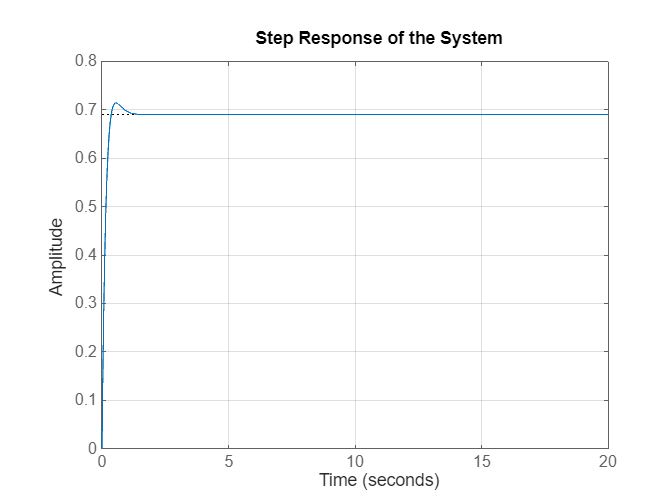

time_span = 0:0.01:20; % Define time vector
figure;
step(sys, time_span); % Step response plot
title('Step Response of the System');
grid on;

## Task 4: Find the poles and zeros

disp('----- Task 4: Poles and Zeros -----');

----- Task 4: Poles and Zeros -----


poles = pole(sys);
zeros = zero(sys);
disp('Poles of the system:');

Poles of the system:


disp(poles);

  -5.0000 + 2.0000i
  -5.0000 - 2.0000i
  -3.0000 + 0.0000i



disp('Zeros of the system:');

Zeros of the system:


disp(zeros);

    -4
    -3



## Task 5: Plot poles and zeros on the s-plane

% Task 5: Plot the Pole-Zero Map
disp('----- Task 5: Pole-Zero Map on s-plane -----');

----- Task 5: Pole-Zero Map on s-plane -----


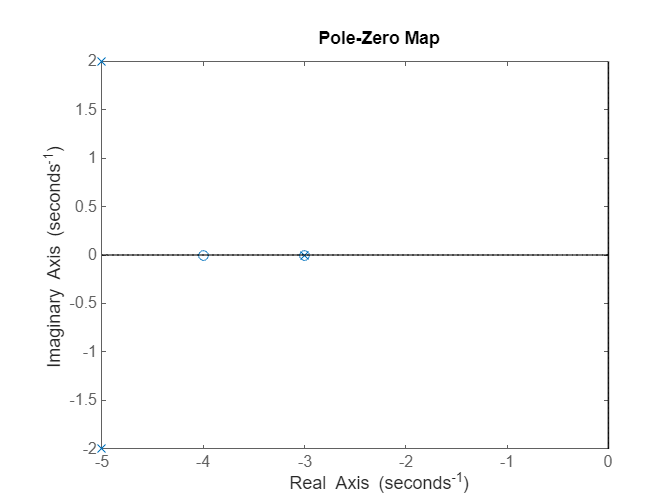

figure;
pzmap(sys); % Plot the pole-zero map
title('Pole-Zero Map');
grid off;
hold on;
xline(0, 'k', 'LineWidth', 1); % Add x-axis
yline(0, 'k', 'LineWidth', 1); % Add y-axis
hold off;

## Task 6: Find natural frequency, damping factor, decay rate, and damped frequency

disp('----- Task 6: System Characteristics -----');

----- Task 6: System Characteristics -----


disp('The poles are stable, as shown in the Pole-Zero Map. Cancelling the pole is acceptable here.');

The poles are stable, as shown in the Pole-Zero Map. Cancelling the pole is acceptable here.



numerator_simplified = [1 4]; % Simplified numerator
denominator_simplified = [1 10 29]; % Simplified denominator
disp('The simplified transfer function:');

The simplified transfer function:


sys_simplified = tf(numerator_simplified, denominator_simplified);

disp('Characteristic equation from derivation, CE = s^3 - ((2 * zeta * wn) + 3) * s^2 + (wn^2 * (6 * zeta * wn) * s + 3 * wn^2')

Characteristic equation from derivation, CE = s^3 - ((2 * zeta * wn) + 3) * s^2 + (wn^2 * (6 * zeta * wn) * s + 3 * wn^2


disp('Denominator equation 1: s^2 + (wn*zeta)s + wn^2');

Denominator equation 1: s^2 + (wn*zeta)s + wn^2


disp('Where wn = sqrt(29), zeta = 10 / (2 * wn)');

Where wn = sqrt(29), zeta = 10 / (2 * wn)



wn = sqrt(29); 
disp(['Natural Frequency (wn): ', num2str(wn), ' rad/s']);

Natural Frequency (wn): 5.3852 rad/s



zeta = 10 / (2 * wn);
disp(['Damping Factor (zeta): ', num2str(zeta)]);

Damping Factor (zeta): 0.92848



disp('Denominator equation 2: s^2 + (2*decay_rate)s+ decay_rate^2+damped_frequency^2')

Denominator equation 2: s^2 + (2*decay_rate)s+ decay_rate^2+damped_frequency^2


disp('Where decay_rate = wn * zeta, damped_frequency = sqrt(wn^2 - decay_rate^2');

Where decay_rate = wn * zeta, damped_frequency = sqrt(wn^2 - decay_rate^2



decay_rate = zeta * wn; 
disp(['Decay Rate: ', num2str(decay_rate), ' rad/s']);

Decay Rate: 5 rad/s



damped_frequency = sqrt(wn^2 - decay_rate^2); 
disp(['Damped Frequency: ', num2str(damped_frequency), ' rad/s']);

Damped Frequency: 2 rad/s


## Task 7: Calculate performance metrics

disp('----- Task 7: Performance Metrics -----');

----- Task 7: Performance Metrics -----


info = stepinfo(sys);
[y, ~] = step(sys, time_span);
steady_state_value = y(end); % Final value
steady_state_error = abs(1 - steady_state_value); % Assuming unit step input

disp('Performance Metrics of the System:');

Performance Metrics of the System:


disp(['Rise Time (s): ', num2str(info.RiseTime)]);

Rise Time (s): 0.23325


disp(['Peak Time (s): ', num2str(info.PeakTime)]);

Peak Time (s): 0.55262


disp(['Settling Time (s): ', num2str(info.SettlingTime)]);

Settling Time (s): 0.8163


disp(['Maximum Percent Overshoot (%): ', num2str(info.Overshoot)]);

Maximum Percent Overshoot (%): 3.5103


disp(['Steady-State Error: ', num2str(steady_state_error)]);

Steady-State Error: 0.31034


## Task 8: Generate Bode plot and find gain/phase margins

% Task 8: Bode Plot and Gain/Phase Margins
disp('----- Task 8: Bode Plot and Margins -----');

----- Task 8: Bode Plot and Margins -----


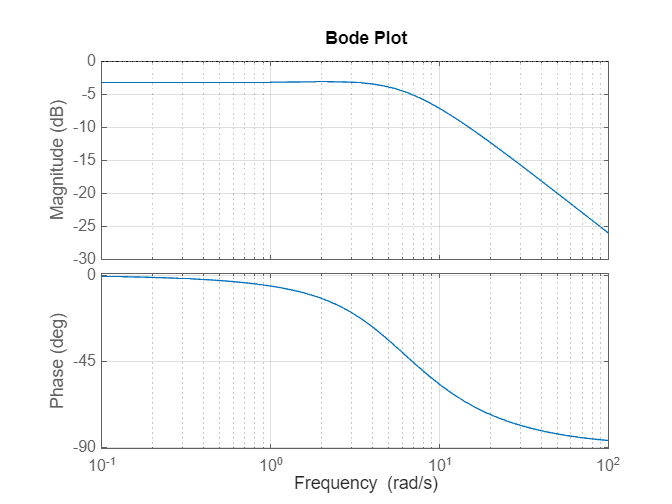

figure;
margin(sys); % Bode plot with margins
title('Bode Plot');
grid on;

% Find gain and phase margins
[gain_margin, phase_margin, ~, ~] = margin(sys);
if gain_margin ~= Inf
    gain_margin_db = 20 * log10(gain_margin);
else
    gain_margin_db = Inf;
end

disp(['Gain Margin (dB): ', num2str(gain_margin_db)]);

Gain Margin (dB): Inf


disp(['Phase Margin (degrees): ', num2str(phase_margin)]);

Phase Margin (degrees): Inf


# Part C: Controllers Design Using MATLAB Live Code

## PID & PI Controller 

disp('----- Part C -----')

----- Part C -----


### PID Controller (Controller 1)


disp('----- PID Controller Analysis [Controller 1] -----');

----- PID Controller Analysis [Controller 1] -----


----- Task 4: CLTF -----
PID Controller CLTF:


$$\frac{0.15\,s^{4}+15.0\,s^{3}+230.0\,s^{2}+1.1e+3\,s+1.5e+3}{s^{4}+26.0\,s^{3}+280.0\,s^{2}+1.1e+3\,s+1.5e+3}$$

----- Task 5: Zeros and Pole -----
PID Controller Zeros:
  -79.0525
  -10.6334
   -4.0000
   -3.0000

PID Controller Poles:
  -9.5386 + 6.7615i
  -9.5386 - 6.7615i
  -3.7784 + 0.0000i
  -3.0000 + 0.0000i

----- Task 6: Step Response Comparison -----


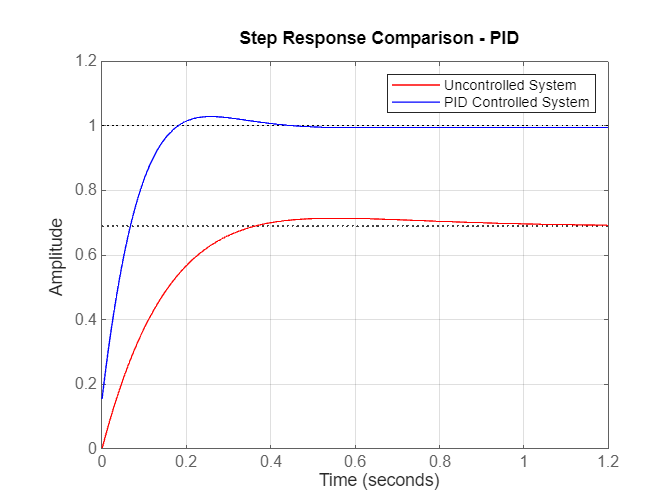

----- Task 7: Bode Plots Comparison -----


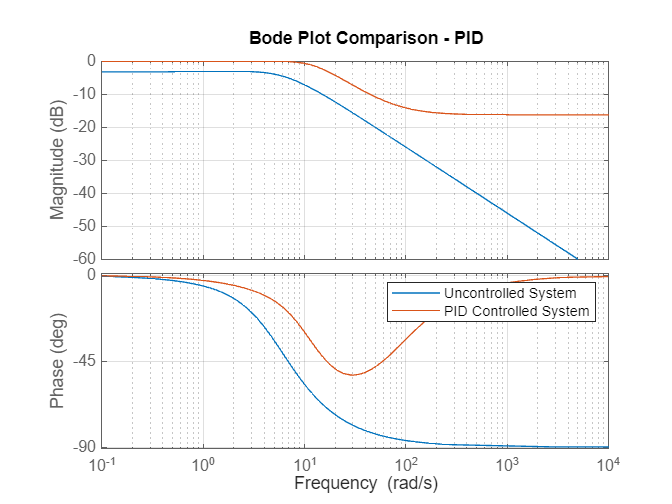

----- Task 8: Performance Metrics Comparison -----
PID Controller Metrics Comparison with Uncontrolled Metrics:
            Metric            Uncontrolled System    PID_Controller
    ______________________    ___________________    ______________

    {'Rise Time (s)'     }          0.23325             0.12098    
    {'Peak Time (s)'     }          0.55262             0.25588    
    {'Settling Time (s)' }           0.8163             0.32786    
    {'Max % Overshoot'   }           3.5103              2.8498    
    {'Steady-State Error'}          0.31034                   0    



PID_Controller(sys, 3.2556, 30.5137, 0.0363, 'PID');

### PI Controller (Controller 2)

disp('----- PI Controller Analysis [Controller 2] -----');

----- PI Controller Analysis [Controller 2] -----


----- Task 4: CLTF -----
PI Controller CLTF:


$$\frac{14.0\,s^{3}+220.0\,s^{2}+1.0e+3\,s+1.5e+3}{s^{4}+27.0\,s^{3}+280.0\,s^{2}+1.1e+3\,s+1.5e+3}$$

----- Task 5: Zeros and Pole -----
PI Controller Zeros:
   -8.5498
   -4.0000
   -3.0000

PI Controller Poles:
 -10.3262 + 5.1084i
 -10.3262 - 5.1084i
  -3.6975 + 0.0000i
  -3.0000 + 0.0000i

----- Task 6: Step Response Comparison -----


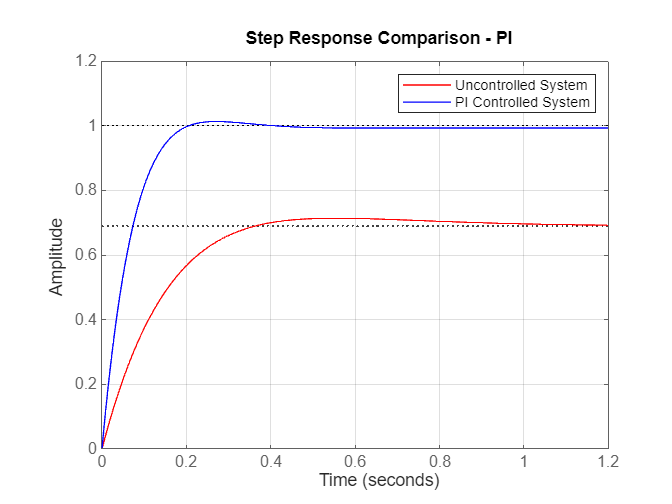

----- Task 7: Bode Plots Comparison -----


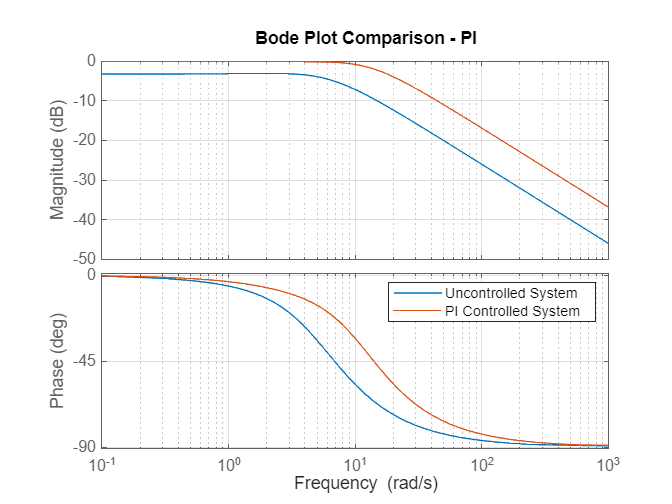

----- Task 8: Performance Metrics Comparison -----
PI Controller Metrics Comparison with Uncontrolled Metrics:
            Metric            Uncontrolled System    PI_Controller
    ______________________    ___________________    _____________

    {'Rise Time (s)'     }          0.23325             0.12083   
    {'Peak Time (s)'     }          0.55262             0.27204   
    {'Settling Time (s)' }           0.8163             0.17778   
    {'Max % Overshoot'   }           3.5103              1.3224   
    {'Steady-State Error'}          0.31034                   0   



PID_Controller(sys, 2.87, 24.538, 0, 'PI');

### Modular Function for PID/PI Analysis

function PID_Controller(sys, Kp, Ki, Kd, label)
    % Task 3: Define the controller transfer function
    if Kd > 0
        Controller = Kp + tf(Ki, [1 0]) + tf([Kd 0], 1); % PID
    else
        Controller = Kp + tf(Ki, [1 0]); % PI
    end

    % Task 4: Display expanded CLTF
    disp('----- Task 4: CLTF -----')
    CLTF = feedback(sys * Controller, 1);
    [z, p, k] = zpkdata(CLTF, 'v'); % Extract zeros, poles, and gain
    syms s;
    numerator = expand(k * prod(s - z));
    denominator = expand(prod(s - p));
    disp([label, ' Controller CLTF:']);
    disp(vpa(numerator / denominator, 2));

    % Task 5: Zeros and poles
    disp('----- Task 5: Zeros and Pole -----')
    disp([label, ' Controller Zeros:']);
    disp(z);
    disp([label, ' Controller Poles:']);
    disp(p);

    % Task 6: Step response comparison
    disp('----- Task 6: Step Response Comparison -----')
    figure;
    step(sys, 'r', CLTF, 'b');
    grid on;
    legend('Uncontrolled System', [label, ' Controlled System']);
    title(['Step Response Comparison - ', label]);

    % Task 7: Bode plot comparison
    disp('----- Task 7: Bode Plots Comparison -----')
    figure;
    bode(sys, CLTF);
    grid on;
    legend('Uncontrolled System', [label, ' Controlled System']);
    title(['Bode Plot Comparison - ', label]);

    % Task 8: Performance metrics
    disp('----- Task 8: Performance Metrics Comparison -----')
    info_sys = stepinfo(sys);
    info_CLTF = stepinfo(CLTF);
    SS_error_sys = abs(1 - dcgain(sys));
    SS_error_CLTF = abs(1 - dcgain(CLTF));

    metrics = {'Rise Time (s)', 'Peak Time (s)', 'Settling Time (s)', 'Max % Overshoot', 'Steady-State Error'};
    plant_values = [info_sys.RiseTime, info_sys.PeakTime, info_sys.SettlingTime, info_sys.Overshoot, SS_error_sys];
    controller_values = [info_CLTF.RiseTime, info_CLTF.PeakTime, info_CLTF.SettlingTime, info_CLTF.Overshoot, SS_error_CLTF];
    comparison_table = table(metrics', plant_values', controller_values', 'VariableNames', {'Metric', 'Uncontrolled System', [label, '_Controller']});

    disp([label, ' Controller Metrics Comparison with Uncontrolled Metrics:']);
    disp(comparison_table);
end

## Comments

The step response and Bode plots allow comparison of time-domain and frequency-domain performance. Both PID and PI controller aims to minimize settling time (<0.5 s), overshoot (<= 4%), and steady-state error (0). A PD controller design is not possible as the steady-state error is not eliminated from the system.